# Funciones


function F= ecuaciones_estacionarias(x,params)
    
    Ls=params.Ls;
    Rs=params.Rs;
    Cdc=params.Cdc;
    Ldc=params.Ldc;
    Rdc=params.Rdc;
    ws=params.ws;
    Ipvmax=params.Ipvmax;
    kpv=params.kpv;
    Vpvmax=params.Vpvmax;

    vdc=params.Vdc;
    isd=params.isd;
    Qs_ref=params.qs;
    
    Vsd=params.Vsd;
    Vsq=params.Vsq;

    isq = x(1);
    mrd = x(2);
    mrq = x(3);
    ipv = x(4);
    mb  = x(5);
    

    F = zeros(5,1);

    F(1)=(1/Ls)*Vsd-(Rs/Ls)*isd+ws*isq-(1/(2*Ls))*mrd*vdc;

    F(2)=(1/Ls)*Vsq-(Rs/Ls)*isq-ws*isd-(1/(2*Ls))*mrq*vdc;

    F(3)=((1-mb)/Cdc)*ipv-(1/(Rdc*Cdc))*vdc+(1/(2*Cdc))*(mrd*isd+mrq*isq);
    
    Vpv=Vpvmax+kpv*log(1-(ipv/Ipvmax));
    F(4)=Vpv/Ldc-((1-mb)/Ldc)*vdc;

    F(5)=Vsd*isq-Qs_ref;
end

function dxdt = prom_dq0(t,x,params,Vsd,Vsq,mrd,mrq,mb)
    
    Ls=params.Ls;
    Rs=params.Rs;
    Cdc=params.Cdc;
    Ldc=params.Ldc;
    Rdc=params.Rdc;
    ws=params.ws;
    Ipvmax=params.Ipvmax;
    kpv=params.kpv;
    Vpvmax=params.Vpvmax;
    
    dxdt=zeros(4,1);
    Vpv=@(ipv) Vpvmax+kpv*log(1-(ipv/Ipvmax));
    vsd=@(t) Vsd-sqrt(3)*220*0.05*(t>20e-3);

    dxdt(1)=(1/Ls)*vsd(t)-(Rs/Ls)*x(1)+ws*x(2)-(1/(2*Ls))*mrd*x(3);
    dxdt(2)=(1/Ls)*Vsq-(Rs/Ls)*x(2)-ws*x(1)-(1/(2*Ls))*mrq*x(3);
    dxdt(3)=((1-mb)/Cdc)*x(4)-(1/(Rdc*Cdc))*x(3)+(1/(2*Cdc))*(mrd*x(1)+mrq*x(2));
    dxdt(4)=Vpv(x(4))/Ldc-((1-mb)/Ldc)*x(3);
end

function [dxdt,A,vsd] = linear_prom_dq0(t,x,params)
    %parametros
    Ls=params.Ls;
    Rs=params.Rs;
    Cdc=params.Cdc;
    Ldc=params.Ldc;
    Rdc=params.Rdc;
    ws=params.ws;
    Ipvmax=params.Ipvmax;
    kpv=params.kpv;
    Vpvmax=params.Vpvmax;
    
    %puntos de equilibrio
    isd0=params.isd0;
    isq0=params.isq0;
    vdc0=params.vdc0;
    ipv0=params.ipv0;
    mrd0=params.mrd0;
    mrq0=params.mrq0;
    mb0=params.mb0;
    Vsd0=params.Vsd;
    Vsq0=params.Vsq;
    
    %perturbacion
    vsd=@(t) Vsd0-sqrt(3)*220*0.05*(t>20e-3);

    dxdt=zeros(4,1);


    A=[-Rs/Ls ws -(mrd0)/(2*Ls) 0;
        -ws -(Rs)/Ls -(mrq0)/(2*Ls) 0;
        mrd0/(2*Cdc) mrq0/(2*Cdc) -1/(Rdc*Cdc) (1-mb0)/Cdc;
        0 0 -(1-mb0)/Ldc -kpv/(Ldc*(Ipvmax-ipv0))];
    B1=[-vdc0/(2*Ls) 0;
        0 -vdc0/(2*Ls);
        isd0/(2*Cdc) isq0/(2*Cdc);
        0 0];
    B2=[0;
        0;
        -ipv0/Cdc;
        vdc0/Ldc];

    E=[1/Ls 0;
        0 1/Ls;
        0 0;
        0 0];
    
    delta_mrd=0;
    delta_mrq=0;
    delta_mb=0;
    delta_vsd=@(t) -sqrt(3)*220*0.05*(t>20e-3);
    delta_vsq=0;

    dxdt=A*[x(1);x(2);x(3);x(4)]+B1*[delta_mrd;delta_mrq]+B2*(delta_mb)+E*[delta_vsd(t);delta_vsq];
end


# C

params.Ls = 15e-3;
params.Rs = 0.5;
params.Cdc = 47e-3;
params.Ldc = 50e-3;
params.Rdc = 2e3;
params.ws = 2*pi*50; 
params.Ipvmax = 8;
params.kpv = 50;
params.Vpvmax=360;

params.Vdc=650;
params.isd=0;
params.qs=5e3;


params.Vsd= sqrt(3)*220;
params.Vsq=0;

x0=[0;0;0;0;0];
[xsolve,fval] = fsolve(@(x) ecuaciones_estacionarias(x,params),x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



isd=params.isd

isd = 0

isq = xsolve(1)

isq = 13.1216

Vdc=params.Vdc

Vdc = 650

ipv = xsolve(4)

ipv = 0.8388

mrd = xsolve(2)

mrd = 1.3627

mrq = xsolve(3)

mrq = -0.0202

mb  = xsolve(5)

mb = 0.4547

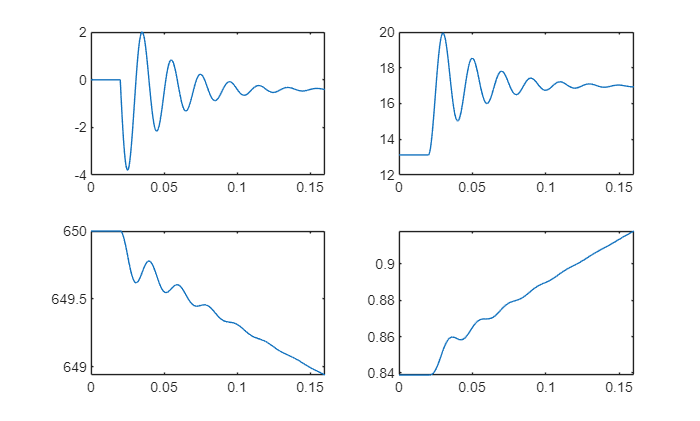


params.isd0=isd;
params.isq0=isq;
params.vdc0=Vdc;
params.ipv0=ipv;
params.mrd0=mrd;
params.mrq0=mrq;
params.mb0=mb;

mr=[mrd mrq];
vs=[params.Vsd params.Vsq];

t=(0:1/10000:160e-3)';
[t,x]=ode45(@(t,x) prom_dq0(t,x,params,vs(1),vs(2),mr(1),mr(2),mb),t,[isd;isq;Vdc;ipv]);

buff=ones(length(t),1);

vsd2=vs(1)-sqrt(3)*220*0.05*(t>20e-3);
Vpv2=params.Vpvmax+params.kpv*log(1-(x(:,4)/params.Ipvmax));
idcp2=(1/2)*(mr(1)*x(:,1)+mr(2)*x(:,2));
idcn2=-(1/2)*(mr(1)*x(:,1)+mr(2)*x(:,2));
Ppv2=x(:,4).*Vpv2;
ps2=(vs(1)*x(:,1))+(vs(2)*x(:,2));
qs=vs(1)*x(:,2)-vs(2)*x(:,1);
mr2=sqrt(2/3)*sqrt((mrd*buff).^2+(mrq*buff).^2);


figure
subplot(2,2,1)
plot(t,x(:,1))
subplot(2,2,2)
plot(t,x(:,2))
subplot(2,2,3)
plot(t,x(:,3))
subplot(2,2,4)
plot(t,x(:,4))

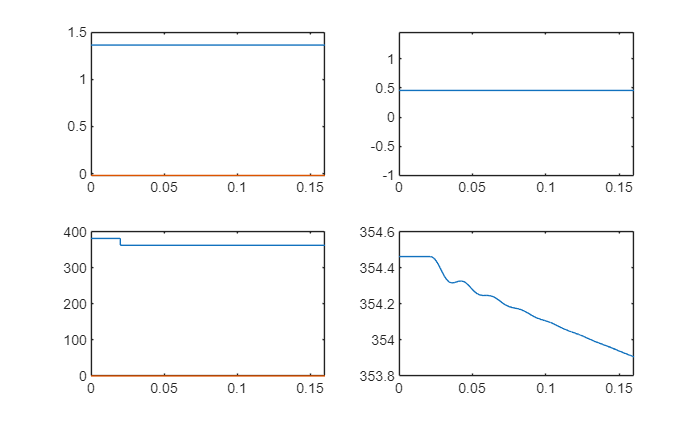


figure
subplot(2,2,1)
plot(t,buff*mr)
subplot(2,2,2)
plot(t,buff*mb)
subplot(2,2,3)
plot(t,[vsd2 vs(2)*buff])
subplot(2,2,4)
plot(t,Vpv2)

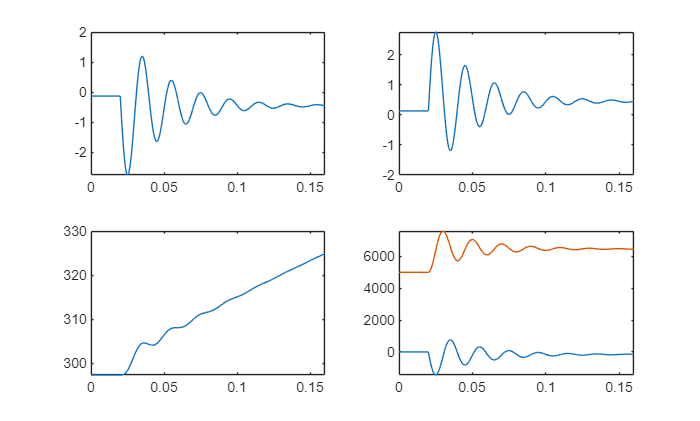



figure
subplot(2,2,1)
plot(t,idcp2)
subplot(2,2,2)
plot(t,idcn2)
subplot(2,2,3)
plot(t,Ppv2)
subplot(2,2,4)
plot(t,[ps2 qs])

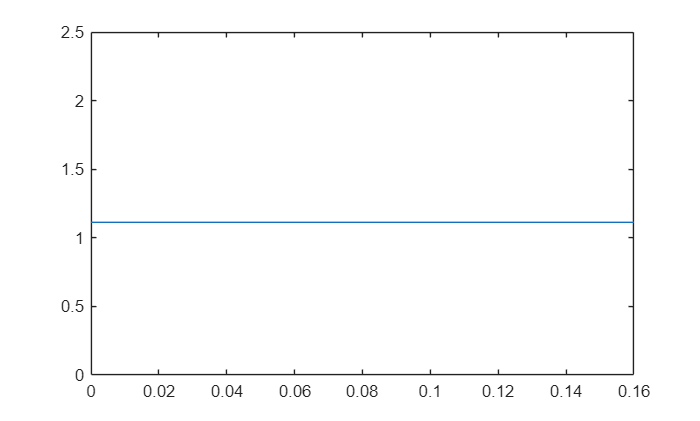


figure
plot(t,mr2)

# D

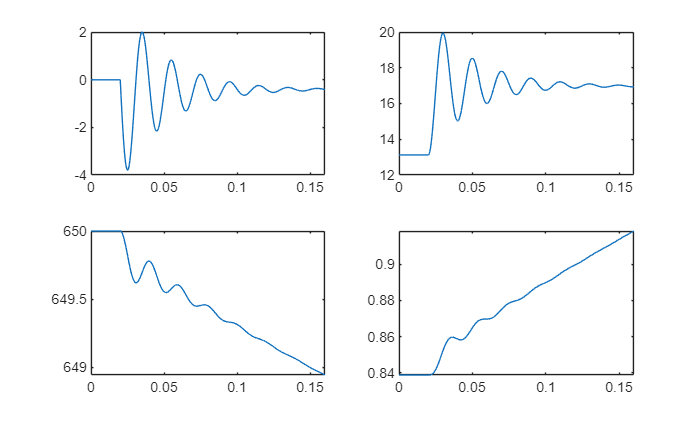

[t,xlin]=ode45(@(t,xlin) linear_prom_dq0(t,xlin,params),t,[0;0;0;0]);

Vpvlin=params.Vpvmax+params.kpv*log(1-((xlin(:,4)+ipv)/params.Ipvmax));


figure
subplot(2,2,1)
plot(t,xlin(:,1))
subplot(2,2,2)
plot(t,xlin(:,2)+isq)
subplot(2,2,3)
plot(t,xlin(:,3)+Vdc)
subplot(2,2,4)
plot(t,xlin(:,4)+ipv)

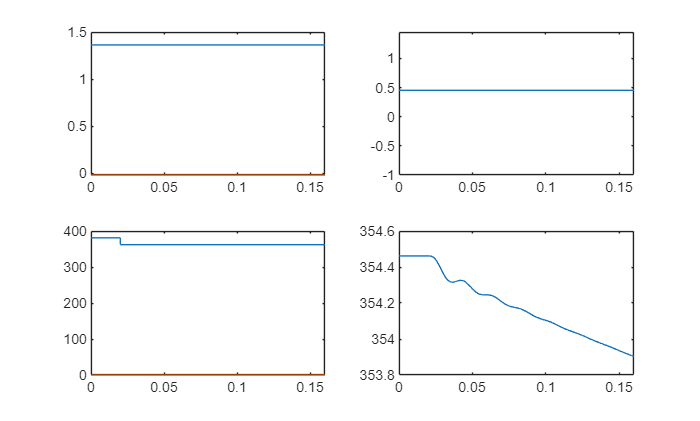



figure
subplot(2,2,1)
plot(t,buff*mr)
subplot(2,2,2)
plot(t,buff*mb)
subplot(2,2,3)
plot(t,[vsd2 vs(2)*buff])
subplot(2,2,4)
plot(t,Vpvlin)


figure


# E

[~,A,~]=linear_prom_dq0(0,[0;0;0;0],params);
eigs(A)

ans = 1.0e+02 *

  -0.3322 + 3.1520i
  -0.3322 - 3.1520i
  -1.3873 + 0.0000i
  -0.0114 + 0.0000i


eigs(A.')

ans = 1.0e+02 *

  -0.3322 + 3.1520i
  -0.3322 - 3.1520i
  -1.3873 + 0.0000i
  -0.0114 + 0.0000i
